x = 0:0.1:2; y = [0:0.1:2]';
[X,Y] = meshgrid(0:0.1:2,0:0.1:2);

Potenziale attrattivo

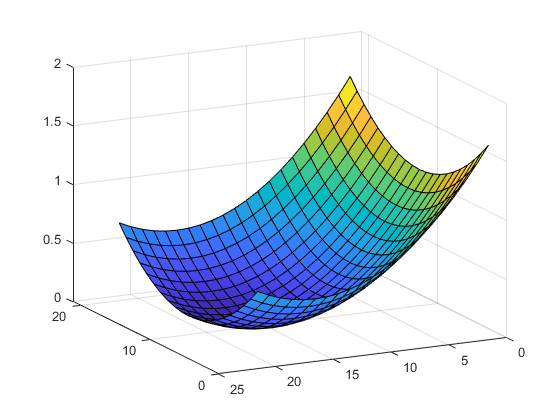

xg = 1; yg = 1.5; xo = 1.5; yo = 1;
Ua = 1/2*((y-yg).^2 + (x-xg).^2);
surf(Ua)
view([-116.70 18.96]);

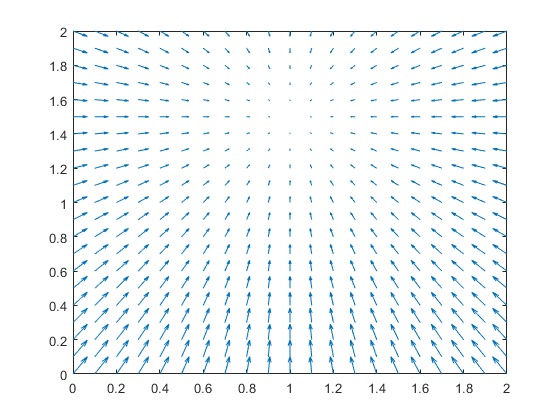

[gx,gy] = gradient(-Ua);
quiver(X,Y,gx,gy)

Potenziale repulsivo 

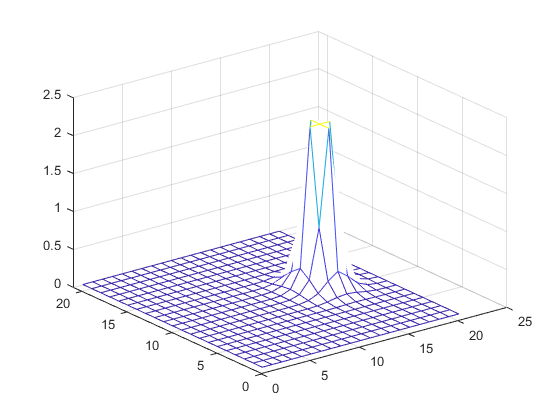

d = sqrt((x-xo).^2 + (y-yo).^2);
Ur =  1/30*((1./d - 1/0.5).^2);
Ur(d > 0.5) = 0; Ur(isinf(Ur)) = 2.133;
mesh(Ur)

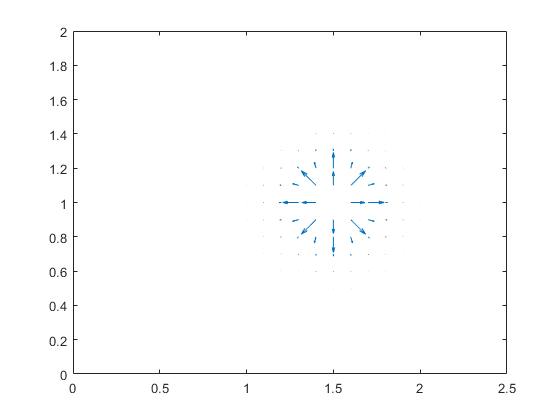

[gx,gy] = gradient(-Ur);
quiver(X,Y,gx,gy)

Potenziale elicoidale

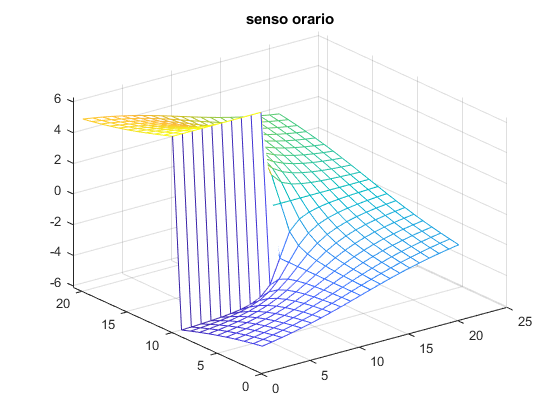

x0 = 1; y0 = 1;
c = 2;

% Forma parametrica
% clearvars
% syms u v r t;
% r = v; t = u;
% x = x0 + 1.5*cos(t);
% y = [y0 + 1.5*sin(t)]';
% z = c*t;
% fsurf(x,y,z,[0 2*pi]);

%Forma cartesiana
pot1 = c*atan2(y-y0,x-x0);
mesh(pot1); title("senso orario");

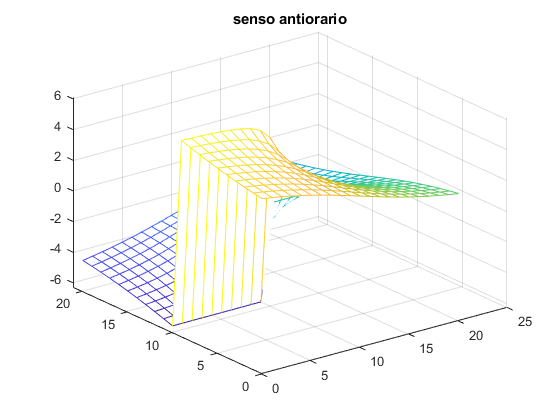

pot2 = -c * atan2(y-y0,x-x0);
mesh(pot2); title("senso antiorario");

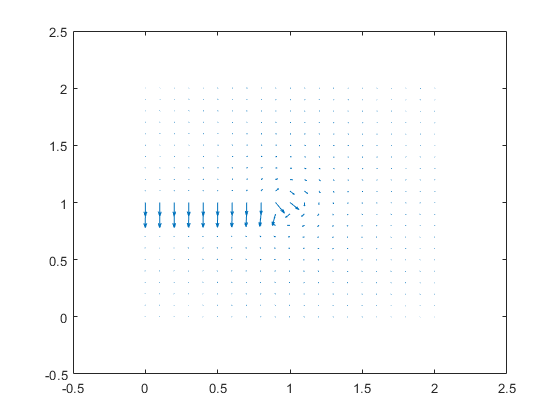

[gx1,gy1] = gradient(pot2);

gx = c*(y-y0)./((x-x0).^2+(y-y0).^2);
gy = c*(x0-x)./((x-x0).^2+(y-y0).^2);

figure;
quiver(X,Y,gx1,gy1);

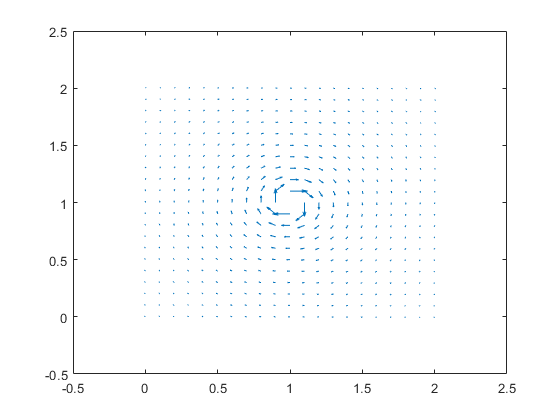

quiver(X,Y,gx,gy);

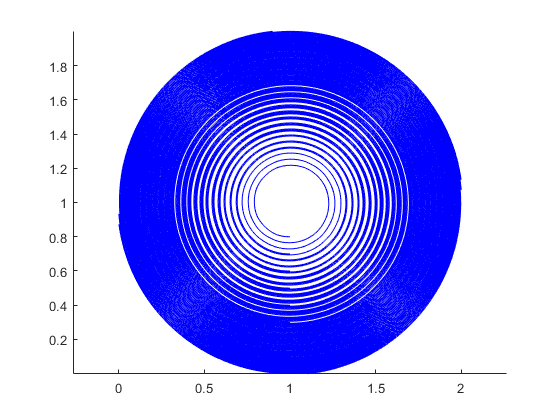

starty = 0.1:0.1:1;
startx = ones(size(starty));
figure;
streamline(X,Y,gx,gy,startx,starty);
axis equal